# A Conversion Matrix Method of Moments (CMMoM) Tutorial

K.C. Kerby-Patel - University of Massachusetts Boston - November 2024

## A. Example Problem

The example problem is a $\frac{\lambda }{300}$ folded copper dipole excited by a plane wave incident at 1 MHz. The folded dipole has a 50 $\Omega$ load at the center of one side (the standard folded dipole feed point) and a time-varying switch at the center of the side opposite the feed. 

### A.1 Parameter setup

Set up constants and model, including signal frequency, pump frequency sweep, and time-varying resistor parameters.

clear all


fs = 1e6;           % incident signal frequency in Hz
fp = sort([0.7:0.1:0.9, 1.1:0.1:9.9, (10:5:150), 81])*1e6; % pump frequency in Hz (sweep vector)
r_closed = 0.3;     % switch closed resistance (ohms)
r_open = 1e5;     % switch open resistance (ohms)
r_duty = 0.5;       % fraction of period switch is closed
K = 5;              % max harmonic index to include in calculation
Z0 = 50;            % load impedance for output port
exdex = K+1;        % incident plane wave at 0th harmonic

### A.2 Load MoM data 

Load compressed MoM data (see 3D image of model). The impedance data has been compressed via a Schur complement method to produce the model's port impedance matrix **ZLLT**. Port 1 is the location of the output and Port 2 is the location of the time-varying load. An incident plane wave voltage excitation vector has been converted by a similar compression operation to produce the open circuit voltages **VPT** observed at the ports of the model when it is excited by a phi-polarized plane wave. Both polarizations of incident plane waves are computed for 14 Lebedev sampling points over a sphere; incidence angle information is stored in the variable **leb**.  Credit to Kurt Schab of Santa Clara University for MoM calculation and compression scripts. Full-wave calculatons performed using AToM [1].

% load compressed fullwave data
% TODO: break this up because this is a stupidly
% broadband sim and may not be entirely trustworthy
load("momDataGeneration/data/comp-loss-folded-dipole-Nleb-14.mat",'ZLLT','VPT','flist','leb') 
N = size(ZLLT,1);   % get number of ports from the compressed data
LP = 2;             % index of port loaded by TV element
OP = 1;             % index of output port
lebdex = 4;         % index of Lebedev point of desired incident plane wave (compare 3 and 4 especially)

Display 3D MoM model and incident wave direction. Plot the MoM model impedance at Port 1 as a sanity check.  We expect this to be capacitive at low frequency because this is the open-circuit impedance matrix, so it looks like there's a gap on the far side as well as at the feed.

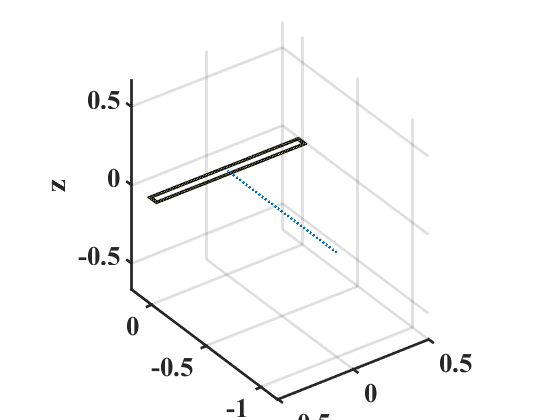

% display MoM model
f = openfig("model.fig");
f2 = figure;
set(f.Children,'Parent',f2)
hold on
% mark incidence angle
plot3([leb.x(lebdex) 0], [leb.y(lebdex) 0], [leb.z(lebdex) 0],':','LineWidth',2)

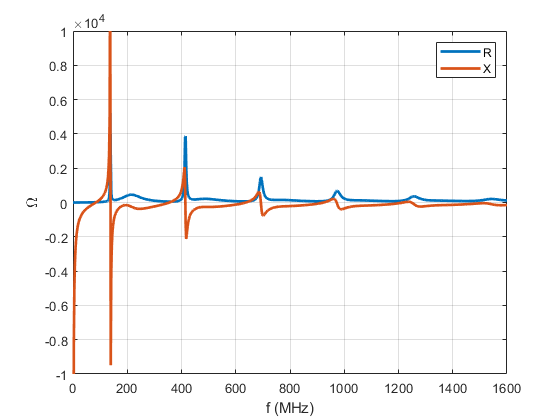


% plot Port 1 impedance to check data
figure
plot(flist*1e-6, squeeze(real(ZLLT(1,1,:))),'LineWidth',2)
hold on
plot(flist*1e-6, squeeze(imag(ZLLT(1,1,:))),'LineWidth',2)
xlabel('f (MHz)')
ylabel('\Omega')
legend({'R';'X'})
grid on
ylim([-1e4 1e4])

### A.2 Set up LTI comparison case

This LTI comparison case is not a particularly good antenna. 

for pp = 1:N
    for qq = 1:N
        ZLTI(pp,qq) = interpComplex(flist, squeeze(ZLLT(pp,qq,:)), fs);
    end
    VLTI(pp,1) = interpComplex(flist, squeeze(VPT(pp,lebdex,:)), fs); %open circuit voltage due to 1 V/m amplitude plane wave
end
ZLLTI = Z0*[1 0; 0 0]; %same load impedance content as ZL later, just not conversionified
ZSOC = 1e6*[0 0; 0 1];
ILTI_oc = (ZLTI+ZLLTI+ZSOC)\VLTI;           % LTI case (switch = approximate open)
PLTI_oc = 0.5*real(ILTI_oc'*(ZLLTI*ILTI_oc));  %switch = open circuit LTI case power

%also calculate power received if the switch is replaced by a short circuit
ILTI_sc = (ZLTI+ZLLTI)\VLTI;           % LTI case (switch = short)
PLTI_sc = 0.5*real(ILTI_sc'*(ZLLTI*ILTI_sc));  %switch = short circuit LTI case power

It's also a good idea to compare to power that would be received by an antenna that maximizes [2] effective aperture for a self-resonant LTI antenna that fits in this rectangular footprint. Material loss was that of copper.

load("ubx.mat",'ubX','fX');  %calculated using method in [2]
Sinc = (1)^2/(2*377); %incident power density from 1 V/m plane wave
Pub = interp1(fX, Sinc*ubX, 1e6);  %power delivered to the upper-bound antenna for this footprint at 1 MHz

## B. Time-Varying Load Representation

### B.1 Conversion Matrix Formulation

A periodically time-varying resistance with fundamental frequency $\omega_p$ can be represented as a Fourier series:


$$r\left(t\right)=\sum_k R_k e^{\textrm{jk}\omega_p t\;}$$


When a periodically time-varying linear device is excited by a source with frequency $\omega_s$, the voltage and current at the terminals of the device may be represented by modulated Fourier series of the form

$v\left(t\right)=e^{j\omega_s t} \sum_k V_k e^{j{k\omega }_p t} \;$ and $i\left(t\right)=e^{j\omega_s t} \sum_k I_k e^{j{k\omega }_p t} \;$,

where the voltage and current harmonic coefficients$V_k$ and $I_k$ are related by


$$V_k =\sum_{\ell } R_{\ell } I_{k-\ell } \;\ldotp$$


If we truncate the sum for some finite maximum harmonic order $K$, this may be rewritten in matrix form as

$\left\lbrack \begin{array}{c}
V_{-K} \\
\vdots \\
V_K 
\end{array}\right\rbrack$ = $\left\lbrack \begin{array}{ccc}
R_0  & \cdots  & R_{-2K} \\
\vdots  & \ddots  & \vdots \\
R_{2K}  & \cdots  & R_0 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
I_{-K} \\
\vdots \\
I_K 
\end{array}\right\rbrack$, or $\hat{\mathbf{V}} =\hat{\mathbf{R}} \hat{\mathbf{I}}$.

The result is a conversion matrix, a well-known technique for representation of time-varying linear circuits (small-signal analysis of devices such as mixers and parametric amplifiers). 

Time-varying conductances may be represented by a conductance conversion matrix $\hat{\mathbf{G}} ={\hat{\mathbf{R}} }^{-1}$. Time-varying inductances and capacitances may similarly be represented by matrices composed of their inductance or capacitance Fourier series coefficients, and the current-voltage relationships are

$\hat{\mathbf{V}} =j\hat{\Omega} \hat{\mathbf{L}} \hat{\mathbf{I}}$ and $\hat{\mathbf{I}} =j\hat{\Omega} \hat{\mathbf{C}} \hat{\mathbf{V}}$, 

where the diagonal matrix $\hat{\Omega}$ contains the harmonic frequencies $\omega_k =\omega_s +k\omega_p$,

$\hat{\Omega} =\left\lbrack \begin{array}{ccc}
\omega_{-K}  & 0 & 0\\
0 & \ddots  & 0\\
0 & 0 & \omega_K 
\end{array}\right\rbrack$.

For a detailed discussion of conversion matrices and their use in lumped microwave circuits, see Maas [2].

#### B.1.1 Maximum harmonic order selection

The choice of maximum harmonic index $K$can have a significant impact on the results. A good rule of thumb is to increase $K$ until further changes don't result in significant changes to the simulation output (received power etc.). It can be more important to use a large value of $K$ if the time-varying component waveform has a lot of high frequency spectral content, which produces strong high-order harmonics.  Larger $K$can also be necessary if the system has a resonance at a high-order harmonic frequency.

### B.2 Set up time-varying load

For a square wave like this example, we could compute the time varying element's Fourier series coefficients analytically, but in the spirit of providing a general technique we'll do it using an FFT.  For different pump frequencies, the Fourier series coefficient values don't change, just the frequencies at which they occur - so we can generate this matrix using an arbitrary period T.

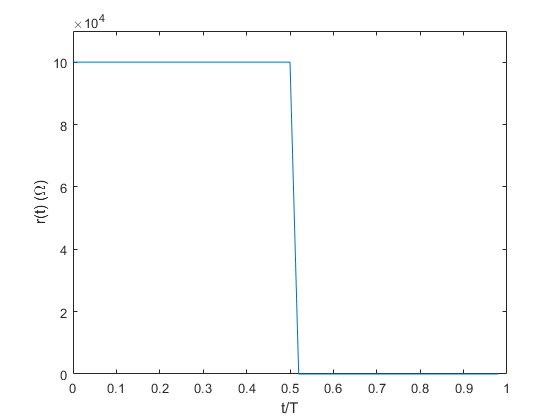

T = 1;         % time-varying resistor period
dt = T/50;     % time window
t = 0:dt:T;
t = t(1:(end-1));
r = 0*t;        % initialize r
r(t>(r_duty*T)) = r_closed;     % closed part of duty cycle
r(~(t>(r_duty*T))) = r_open;    % open part

figure
plot(t/T, r)
xlabel('t/T')
ylabel('r(t) (\Omega)')
ylim([0 1.1*r_open])

### B.3 Compute conversion matrix

Find the Fourier series coefficients for time-varying load that correspond to harmonics to be included in simulation, then populate the time-varying load impedance conversion matrix with them.

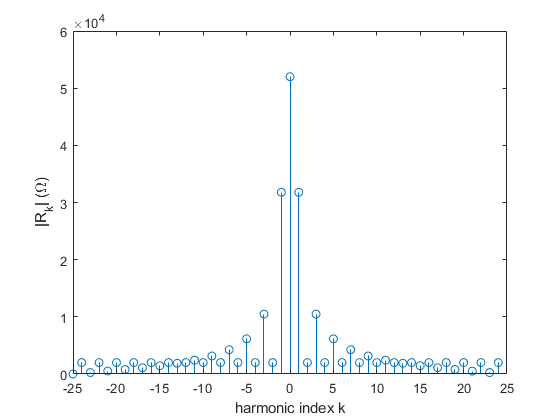

Rcoeffs = fft(r)/length(r);     % Fourier coefficients of r

figure
stem((1:length(Rcoeffs))-1-length(Rcoeffs)/2,fftshift(abs(Rcoeffs)))
xlabel('harmonic index k')
ylabel('|R_k| (\Omega)')

As expected for a square wave with nonzero mean, **Rcoeffs** contains a static component at k=0, and its even-numbered Fourier series coefficients other than the 0th are nearly zero.

To fill the time-varying resistance conversion matrix, we select the elements of **Rcoeffs** associated with the harmonics defined in the variable **harms**.  The resistance conversion matrix has a Toeplitz form and the conjugate symmetry that is expected of Fourier coefficients of time-domain real signals, with negative-index elements of **Rcoeffs** above the diagonal and positive-index elements below the diagonal.

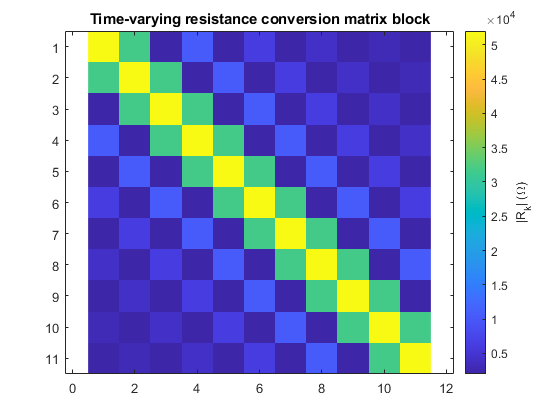

Rblock = toeplitz(conj(Rcoeffs(1:(2*K+1))));    % make CM block by truncating coefficients, forming matrix
R = zeros(N*(2*K+1));                           % initialize whole-model CM
rindices = ((LP-1)*(2*K+1)+1):(LP*(2*K+1));     % select indices
R(rindices, rindices) = Rblock;                 % populate CM in correct port

figure
imagesc(abs(Rblock))
cr=colorbar;
cr.Label.String = '|R_k| (\Omega)';
title('Time-varying resistance conversion matrix block')
axis equal

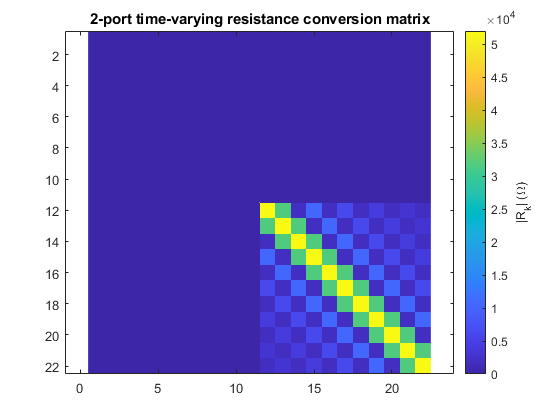

figure
imagesc(abs(R))
cr=colorbar;
cr.Label.String = '|R_k| (\Omega)';
title('2-port time-varying resistance conversion matrix')
axis equal

## C. "Conversionify" LTI Model Elements

CMMoM [3] hybridizes conversion matrices with an impedance-based description of some LTI electromagnetic system. Uncompressed MoM data may be loaded with distributed space-time-varying loads at any or all points on the model structure. Compressed data may be loaded at any of the port locations represented by the compressed impedance matrix. It should be noted that, once compressed, the impedance and open-circuit voltage information needed for CMMoM is equivalent to the port impedance matrix and voltages produced by any other frequency-domain simulation method. 

It doesn't matter whether you choose to group your conversion matrix method of moments simulation by port or by frequency.  Here we will group them by port, so the total CMMoM representation of the model is made up of **N x N** blocks, where **N** is the number of ports, and each block represents all conversion between harmonic frequencies at a particular port.  The impedance conversion matrices of LTI model elements are made up of diagonal blocks because there is no conversion between harmonic frequencies in LTI components.  

### C.1 Conversionified frequency-independent model elements

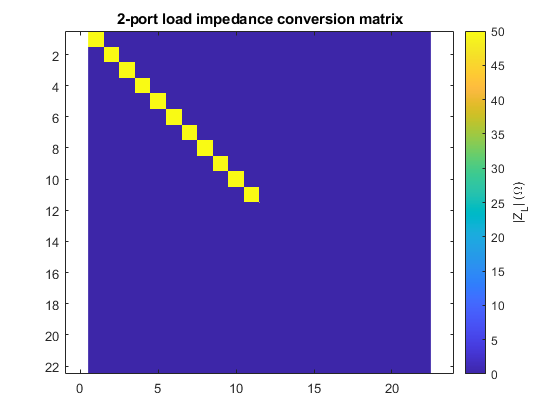

ZL = zeros(size(R));                            % initialize
Lindices = ((OP-1)*(2*K+1)+1):(OP*(2*K+1));     % choose the right indices
ZL(Lindices, Lindices) = Z0*eye(2*K+1);         % diagonal block for load

figure
imagesc(abs(ZL))
cr=colorbar;
cr.Label.String = '|Z_L| (\Omega)';
title('2-port load impedance conversion matrix')
axis equal

### C.2 Conversionified fullwave model impedance matrix, begin pump frequency sweep

Populate the port-wise blocks of the impedance conversion matrix describing electromagnetic interactions in the system. For model elements with frequency-dependent impedance, this step must be repeated every time the value of signal frequency **fs** or pump frequency **fp** is changed.  In this example, we only sweep pump frequency.

ZMoM = zeros(N*(2*K+1));                % initialize ZMoM
P = zeros(N*(2*K+1), length(fp));       % initialize output power


for fdex = 1:length(fp)    
    Voc = zeros(N*(2*K+1),1);               % initialize open circuit voltages
    for pp = 1:N
        thisPort = (pp-1)*(2*K+1);      %port indexer
        for qq = 1:N
            otherPort = (qq-1)*(2*K+1); % port indexer
            for hh = 1:(2*K+1)
                % interpolate MoM data for each harmonic frequency
                ZMoM(thisPort+hh, otherPort+hh) = ...
                    interpComplex(flist, squeeze(ZLLT(pp,qq,:)),... 
                    abs(fs+(hh-(K+1))*fp(fdex)));
                    % interpComplex is a basic helper function; provided
                if (fs+(hh-(K+1))*fp(fdex))<0   % handle negative harmonic frequencies
                    ZMoM(thisPort+hh, otherPort+hh) = conj(ZMoM(thisPort+hh, otherPort+hh));
                end
            end
        end
        

### C.3 Populate excitation voltages

As part of the compression process, we also compute the open-circuit voltages induced on each port of the compressed fullwave model in response to an incident plane wave.  These must be computed for each excitation frequency but don't actually change when we change pump frequency if only the 0th harmonic is excited.  If multiple harmonic frequencies are excited (i.e. in broadband noise environments), this variable does need to be repopulated for every **fp** step.

        
        Voc(thisPort+exdex,1) = interpComplex(flist, squeeze(VPT(pp,lebdex,:)),abs(fs));  % incident plane wave open ckt voltages
        if (fs)<0           %handle negative harmonic frequencies
            Voc(thisPort+exdex,1) = conj(Voc(thisPort+exdex,1));
        end


In addition, we should check for and handle degenerate harmonics. If any of the harmonics is the same in magnitude as the excitation frequency, a real-valued time domain signal will excite both.  (This harmonic will always have opposite sign from the excitation frequency in single-pumped systems.) We populate this harmonic with **conj(Voc(thisport + exdex))** and print a warning that suggests you should do a sweep on incident signal phase.

        
        if any(fs + (fs+(-K:K)*fp(fdex)) == 0)
            dindex = find(fs + (fs+(-K:K)*fp(fdex)) == 0);
            Voc(thisPort+dindex,1) = conj(Voc(thisPort+exdex,1));
            warning(['Degenerate harmonic found at fp = ' num2str(fp(fdex)*1e-6) ' MHz. You should do a sweep on incident signal phase.'])
        end
    end



Visualize (for explanatory purposes) **ZMoM** and **Voc** at one pump frequency.

    %visualize Voc
    if fp(fdex)==81e6
        figure
        imagesc(abs(Voc))
        axis equal
        cv=colorbar;
        cv.Label.String = '|V_{oc}| (V)';
        drawnow
    end

    %visualize an example of ZMoM (only showing one value of fp)
    if fp(fdex)==81e6
        figure
        imagesc(abs(ZMoM))
        axis equal
        cz=colorbar;
        cz.Label.String = '|Z_{MoM}| (\Omega)';
        drawnow
    end

## D. Output

Compute the power delivered to the load at each harmonic for each pump frequency value.  

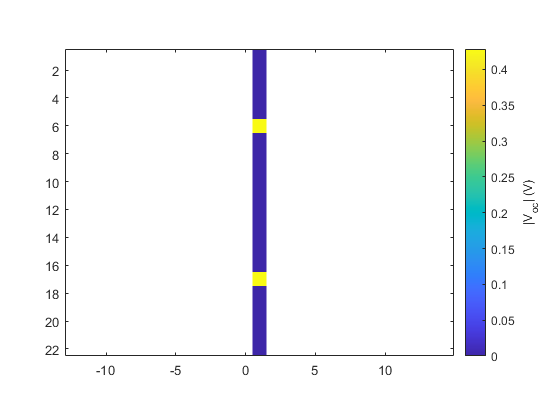

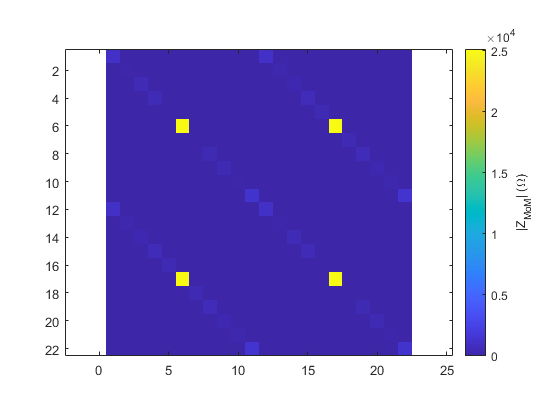

    I = (ZMoM+ZL+R)\Voc;                        % solve for multifrequency port currents
    P(:,fdex) = 0.5*real(conj(I).*(ZL*I));      % load power
end

### D.1 Output Harmonics vs. Pump Frequency

Finally, these plots show the **power received in each harmonic frequency index** as a function of pump frequency, for a fixed signal frequency fs = 1 MHz. Note that as **fp** is swept, the actual value of each harmonic frequency except the 0th also changes.  Each trace represents the power output at a particular harmonic index **k**,

%visualize power delivered to the load as a function of pump frequency
harmfig = figure;
harmfig.Position(3:4) = [1000,1000];
semilogy(fp*1e-6,P(1:(2*K+1),:),'LineWidth',2)
hold on
xlabel('f_p (MHz)')
ylabel('P_L (W)')

%black dotted line marks "this antenna but LTI with the switch open" comparison
semilogy([min(fp) max(fp)]*1e-6, [PLTI_oc(1) PLTI_oc(1)],':k','LineWidth',2)
grid on


%black dashed line marks "this antenna but LTI with the switch open" comparison
semilogy([min(fp) max(fp)]*1e-6, [PLTI_sc(1) PLTI_sc(1)],'--k','LineWidth',2)
grid on

%black solid line marks LTI upper bound comparison
semilogy([min(fp) max(fp)]*1e-6, [Pub Pub],'k','LineWidth',2)
grid on

Selecting a particular pump frequency is equivalent to choosing a vertical slice of this plot (red line):

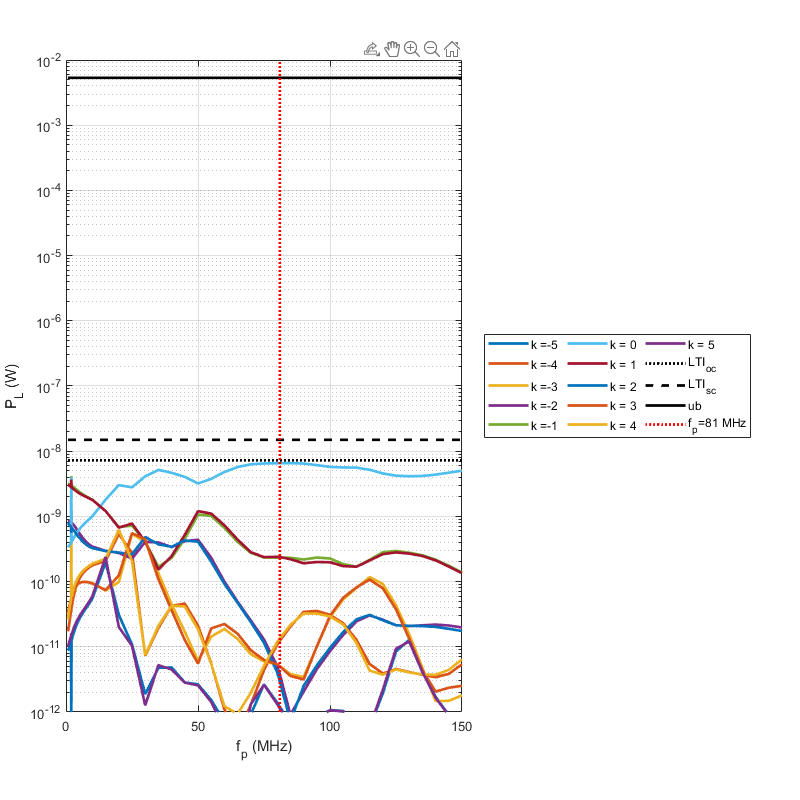

semilogy([81e6 81e6]*1e-6, [1e-13 1e-2],':r','LineWidth',2)
ylim([1e-12 1e-2])
legend([strcat(repmat('k = ', (2*K+1), 1), num2str((-K:K)')); "LTI_{oc}";"LTI_{sc}";"ub";"f_{p}=81 MHz"],'NumColumns',3,'Location','eastoutside')

### D.2 Output Spectrum

The output spectrum for any pump frequency is obtained by calculating the frequency for each harmonic number.  Some harmonic frequencies are mathematically negative but that's not observable in real-valued time-domain signals; they appear on the positive output frequency axis.  

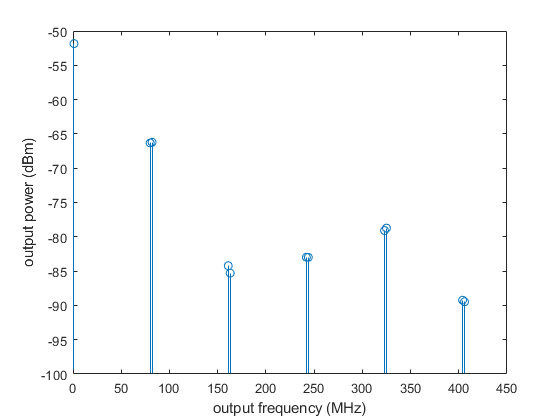

pindex = find(fp==81e6);
fout = abs(fs + (-K:K)*fp(pindex)); %some harmonic frequencies are negative 
figure
stem(fout/1e6, 10*log10(P(1:(2*K+1),pindex)/1e-3),'BaseValue',-100)
xlabel('output frequency (MHz)')
ylabel('output power (dBm)')

## References

- Czech Technical University in Prague, “Antenna toolbox for MATLAB (AToM).” http://www.antennatoolbox.com/atom, 2023.

- M. Gustafsson and M. Capek, "Maximum Gain, Effective Area, and Directivity," *IEEE Transactions on Antennas and Propagation*, vol. 67, no. 8, pp. 5282-5293, 2019.

- S. A. Maas, *Nonlinear Microwave and RF Circuits*. Norwood, MA: Artech House, 2nd ed., 2003.

- S. F. Bass, A. M. Palmer, K. R. Schab, K. C. Kerby-Patel, and J. E. Ruyle, “Conversion matrix method of moments for time-varying electromagnetic analysis,” *IEEE Transactions on Antennas and Propagation*, vol. 70, no. 8, pp. 6763–6774, 2022.